Ali Saeizadeh - 810196477

# WLC CA - OFDM Implementation

## Part F: Header Compensation

## Transmitter

#### Initilization & Generate Random Bits

cd 'F:\University\Semester IIX 2021\Wireless\Semester 2021\CA'
clear all; clc; close all;
wlc_init;
% rng(1);
pkt_size = 10^7;
b_tx = bit_gen(pkt_size, k);
n_c = 400;
% num_sym_subcarrier = 30;
% num_frames = ceil(pkt_size / (n_c * num_sym_subcarrier))
sfc = ceil(2^13/n_c)

sfc = 21

num_sym_subcarrier = sfc

num_sym_subcarrier = 21

num_frames = ceil(length(b_tx) / (sfc * n_c))

num_frames = 1191

num_sym_frame = sfc * n_c

num_sym_frame = 8400

Adding Header

hdr_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k)

hdr_bit =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     1     1
     0     0
     1     1


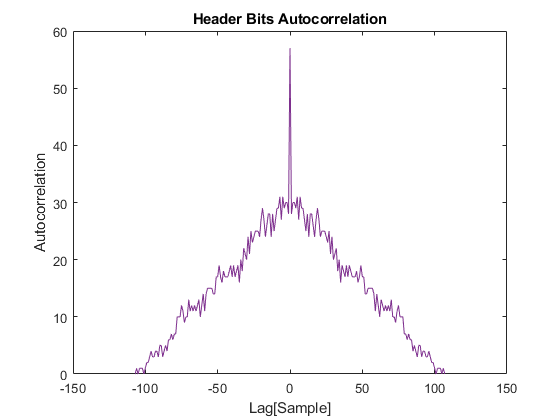

[corr_out_rx, lag] = xcorr(hdr_bit);
plot(lag, corr_out_rx);
xlabel('Lag[Sample]')
ylabel('Autocorrelation')
title('Header Bits Autocorrelation')

[corr_out_rx_max, idx_max] = max(corr_out_rx)

corr_out_rx_max =     57    57    57    57


idx_max =    108   108   108   108


size(hdr_bit)

ans =    108     2


hdr = [hdr_bit ; zeros(sfc * n_c - size(hdr_bit,1),2)];
size(hdr)

ans =         8400           2


b_tx = [hdr ; b_tx];
num_frames =  num_frames+ 1

num_frames = 1192

#### Generating Symbols

flg_gray_encode = 0;
if(flg_gray_encode == 1)
    b_code = gray_code(k);    
else
    b_code = non_code(k);
end 

sym_idx = zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    sym_idx(i,1) = find(sum(b_code == b_tx(i,:),2) == k);
end
sym_idx = sym_idx - 1;
size(sym_idx)

ans =     10008400           1


#### QPSK Modulation

% [cons, Es_avg] = constellation(M, modulation)
% mod_sym = zeros(size(sym_idx));
% for i=1:size(sym_idx,1)
%     mod_sym(i,1) = cons(sym_idx(i,1));
% end
% mod_sym;

#### Frame Divider & Serial to Parallel

% Data = zeros([num_sym_subcarrier,n_c,num_frames]);
% size(Data)
% for i=1:num_frames-1
%     zero_pad_size = (num_sym_frame)- length(sym_idx)
% % sym_idx = [sym_idx; zeros((num_frames * num_sym_subcarrier * n_c) - length(sym_idx),1)];
% % Data = reshape(sym_idx,[num_sym_subcarrier,n_c,num_frames]);
% end

zero_pad_size = (sfc * num_frames * n_c) - length(sym_idx)

zero_pad_size = 4400

sym_idx = [sym_idx; zeros((num_frames * num_sym_subcarrier * n_c) - length(sym_idx),1)];
Data = reshape(sym_idx,[num_sym_subcarrier,n_c,num_frames]);
size(Data)

ans =           21         400        1192


#### Adding  Reference Row

ref_row = randi(4,1,size(Data,2),size(Data,3)) - 1;
Data1 = cat(1,ref_row, Data);

#### DPSK Modulation

Data2 = zeros(size(Data1));
Data2(1,:,:) = Data1(1,:,:);
for f = 2:num_sym_subcarrier + 1
    Data2(f,:,:) = mod(Data1(f - 1,:,:) + Data1(f,:,:), M);
end
Data2 = mod(Data2, M);

#### QPSK Signal Replacement

[cons, Es_avg] = constellation(M, modulation)

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

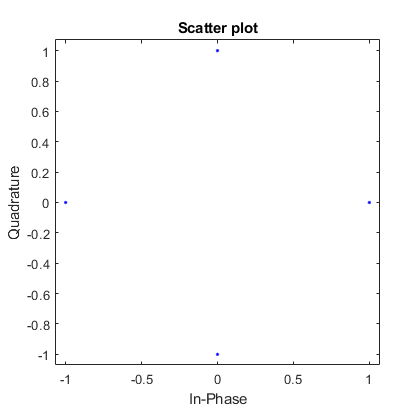

scatterplot(cons)

mod_sym = zeros(size(Data2));
for i=1:size(Data2,1)
    for j = 1:size(Data2,2)
        for k=1:size(Data2,3)
            mod_sym(i,j,k) = cons(Data2(i,j,k) + 1);
        end
    end
end
Data3 = mod_sym;

#### IFFT bins Allocation

Data4 = zeros(num_sym_subcarrier + 1, ifft_size, num_frames);
Data4(:,carriers,:) = Data3;
Data4(:,conj_carriers,:) = conj(Data3);

#### IFFT

ofdm_tx = zeros(size(Data4));
for i =1:num_frames
    ofdm_tx(:,:,i) = real(ifft(Data4(:,:,i),ifft_size,2));
end
% hdr_smpl = ofdm_tx(1:size(hdr_bit,1))

#### Adding CP

end_symb = size(ofdm_tx, 2) 

end_symb = 1024

size(ofdm_tx(:,(end_symb-guard_time+1):end,:))

ans =           22         256        1192


ofdm_tx_cp = cat(2,ofdm_tx(:,(end_symb-guard_time+1):end,:), ofdm_tx);
size(ofdm_tx_cp)

ans =           22        1280        1192


hdr_smpl = reshape(ofdm_tx_cp(:,:,1),size(ofdm_tx_cp(:,:,1),1)*size(ofdm_tx_cp(:,:,1),2),1);
size(hdr_smpl)

ans =        28160           1


#### Parallel to Serial

ofdm_tx_cp_serial = reshape(ofdm_tx_cp, size(ofdm_tx_cp,1)*size(ofdm_tx_cp,2),size(ofdm_tx_cp,3));

SNR = 20:50

SNR =     20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


ber_header = zeros(size(SNR));
chnl_delay_in_smpl = 10;
size(hdr_bit)

ans =    108     2


% hdr_smpl = ofdm_tx_cp_serial(1:size(hdr_bit,1))

## Channel

#### Clipping

for s=1:length(SNR)
ofdm_tx_cp_serial_delayed = [randn(chnl_delay_in_smpl,num_frames) + 1i * randn(chnl_delay_in_smpl,num_frames); ofdm_tx_cp_serial]; 
clipping = 3;
clipped_peak = (10^(0-(clipping/20)))*max(abs(ofdm_tx_cp_serial_delayed));
ofdm_tx_cp_serial_clipped = ofdm_tx_cp_serial_delayed;
for i=1:1:size(ofdm_tx_cp_serial_delayed,2)
    ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i),i) = clipped_peak(i) .* ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i), i) ./ abs(ofdm_tx_cp_serial_clipped(abs(ofdm_tx_cp_serial_clipped(:,i))>=clipped_peak(i),i));
end

#### AWGN Channel

SNR_dB = SNR(s);
ofdm_rx_cp_serial = ofdm_tx_cp_serial_clipped;
Eb =  Es_avg/log2(M);
EbNo = db2pow(SNR_dB);
var_noise = (Eb ./ EbNo);
mean_noise = 0;
noise_smpl = sqrt(var_noise/2) .* (randn(size(ofdm_rx_cp_serial)) + 1i * randn(size(ofdm_rx_cp_serial))) + mean_noise;
% noise_smpl = sqrt(var_noise) .* (randn(size(ofdm_rx_cp_serial)) + mean_noise);
ofdm_rx_cp_serial = ofdm_rx_cp_serial + noise_smpl;

## Reciever

[r,lag] = xcorr(ofdm_rx_cp_serial(:,1), hdr_smpl);
[corr_out_rx_max, idx_max] = max(r)

corr_out_rx_max = 19.5780 - 0.0529i

idx_max = 28180

corr_out_rx_max = 19.6314 + 0.1982i

idx_max = 28180

corr_out_rx_max = 19.2917 - 0.0010i

idx_max = 28180

corr_out_rx_max = 19.8656 + 0.2634i

idx_max = 28180

corr_out_rx_max = 19.6409 - 0.1763i

idx_max = 28180

corr_out_rx_max = 19.4496 + 0.0205i

idx_max = 28180

corr_out_rx_max = 19.3385 - 0.0835i

idx_max = 28180

corr_out_rx_max = 19.4985 + 0.1424i

idx_max = 28180

corr_out_rx_max = 19.6072 - 0.0464i

idx_max = 28180

corr_out_rx_max = 19.4912 - 0.0099i

idx_max = 28180

corr_out_rx_max = 19.6071 - 0.0230i

idx_max = 28180

corr_out_rx_max = 19.5375 - 0.1570i

idx_max = 28180

corr_out_rx_max = 19.5749 + 0.0481i

idx_max = 28180

corr_out_rx_max = 19.5532 - 0.0792i

idx_max = 28180

corr_out_rx_max = 19.5681 + 0.0255i

idx_max = 28180

corr_out_rx_max = 19.4907 - 0.0179i

idx_max = 28180

corr_out_rx_max = 19.5107 + 0.0114i

idx_max = 28180

corr_out_rx_max = 19.5122 + 0.0388i

idx_max = 28180

corr_out_rx_max = 19.4733 - 0.0391i

idx_max = 28180

corr_out_rx_max = 19.4980 - 0.0109i

idx_max = 28180

corr_out_rx_max = 19.5271 - 0.0149i

idx_max = 28180

corr_out_rx_max = 19.5049 - 0.0367i

idx_max = 28180

corr_out_rx_max = 19.5183 + 0.0094i

idx_max = 28180

corr_out_rx_max = 19.5246 - 0.0115i

idx_max = 28180

corr_out_rx_max = 19.5351 - 0.0143i

idx_max = 28180

corr_out_rx_max = 19.5333 - 0.0094i

idx_max = 28180

corr_out_rx_max = 19.5360 - 0.0048i

idx_max = 28180

corr_out_rx_max = 19.5367 + 0.0126i

idx_max = 28180

corr_out_rx_max = 19.5276 - 0.0035i

idx_max = 28180

corr_out_rx_max = 19.5296 + 0.0005i

idx_max = 28180

corr_out_rx_max = 19.5209 - 0.0034i

idx_max = 28180

estimated_time_delay = lag(idx_max) 

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

estimated_time_delay = 10

if(estimated_time_delay == chnl_delay_in_smpl)
    ofdm_rx_cp_serial = ofdm_rx_cp_serial(estimated_time_delay + 1:end,:);
else
    disp('wrong estimation')
    ofdm_rx_cp_serial = ofdm_rx_cp_serial(chnl_delay_in_smpl + 1:end,:);
end


Serial to Parallel

size(ofdm_rx_cp_serial)

ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ans =        28160        1192


ofdm_rx_cp_parallel = reshape(ofdm_rx_cp_serial,[floor(size(ofdm_rx_cp_serial,1)/(ifft_size + guard_time)), ifft_size + guard_time, num_frames]);

CP Removal

ofdm_rx_parallel = ofdm_rx_cp_parallel(:,guard_time + 1:end,:);

FFT

rx_carriers_bins = zeros(size(ofdm_rx_parallel));
for i =1:num_frames
    rx_carriers_bins(:,:,i) = fft(ofdm_rx_parallel(:,:,i),ifft_size,2);
end

Extract Carriers from FFT bins

rx_carriers = rx_carriers_bins(:,carriers,:);

DPSK Demodulation

[cons, Es_avg] = constellation(M, modulation);
ofdm_cons = reshape(cons,1,1,1,4);
[det_sym] = min_dist_detector(rx_carriers, cons);
similarity = det_sym == (ofdm_cons);
[v,det_sym_idx] = max(similarity,[],4);
det_sym_idx = det_sym_idx - 1;


demod_rx = zeros(size(det_sym_idx));
demod_rx(1,:,:) = det_sym_idx(1,:,:);


for i=2:num_sym_subcarrier + 1
    demod_rx(i,:,:) = mod(det_sym_idx(i,:,:) -  demod_rx(i-1,:,:),M);
end

demod_rx = demod_rx(2:end,:,:);

Parallel to Serial

demod_rx_serial = reshape(demod_rx,size(demod_rx,1)*size(demod_rx,2)*size(demod_rx,3),1);
det_rx_serial = demod_rx_serial(:,1);

Estimated Output

det_rx_serial = mod(det_rx_serial,M);
det_bit = b_code(det_rx_serial + 1,:);
det_bit = det_bit(1:end - zero_pad_size,:);


ber_header(s) = sum(sum(det_bit ~= b_tx))/(size(det_bit, 1)*size(det_bit, 2));
end

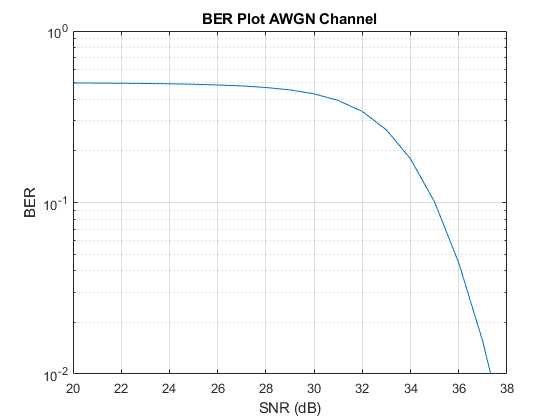

semilogy(SNR,ber_header)
grid on
title('BER Plot AWGN Channel')
ylabel('BER')
xlabel('SNR (dB)')
ylim([1e-2 1])

save('ber_header.mat',"ber_header")

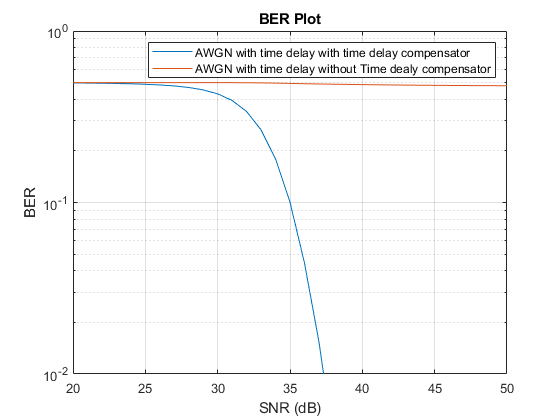

load('ber_delay.mat');
load('ber_header.mat');
semilogy(SNR,[ber_header;ber_delay])
legend 'AWGN with time delay with time delay compensator' 'AWGN with time delay without Time dealy compensator'
grid on
title('BER Plot')
ylabel('BER')
xlabel('SNR (dB)')
ylim([1e-2 1])